# Hi

## Clear Workspace

clear
close all
clc


## Defining Our Dummy Radiation Pattern

%When we have a proper csv file for the radiation pattern 
%of our accepted horn, that file will replace the dummy data
data = readtable("Final_antenna_horn_gain_plot.csv");

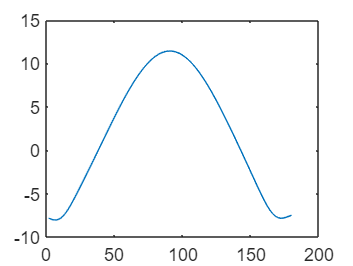

theta_prime = table2array(data(2:end, 3));
g_f = table2array(data(2:end, 4));
plot(theta_prime, g_f);

## Creating the Efficiency Equation

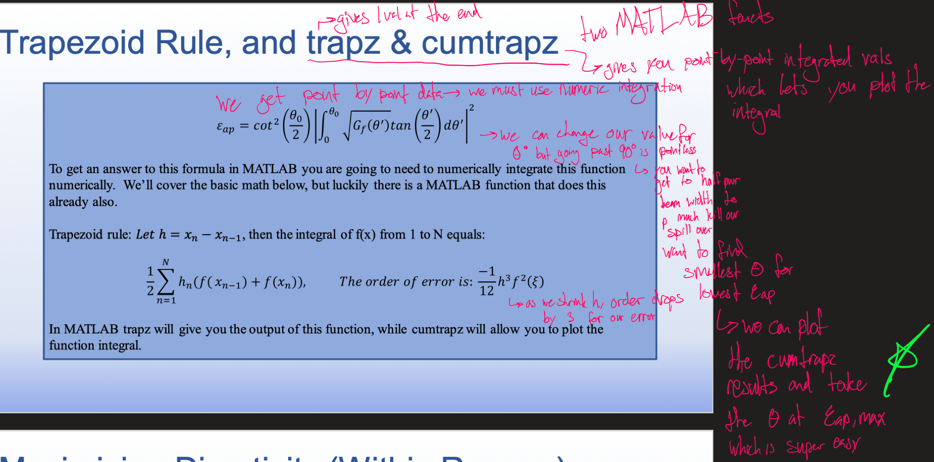

%We are going to get a radiation patern that is swept across some theta prime.
%We want to use the aperture efficiency equaiton (pictured above) to
%sweep across form 0 to different stopping angles (theta_o) until we find
%one that gives us the largest efficiency
%Note that theta_o represents the angle from the center of the dish to the
%edge of the dish

%Defining parts of the equation
integrand = sqrt(g_f).*tan(theta_prime/2);
theta_o = linspace(0,pi/2,length(integrand))

theta_o =          0    0.0176    0.0353    0.0529    0.0706    0.0882    0.1059    0.1235    0.1412    0.1588    0.1765    0.1941    0.2118    0.2294    0.2471    0.2647    0.2824    0.3000    0.3177    0.3353    0.3530    0.3706    0.3883    0.4059    0.4236    0.4412    0.4589    0.4765    0.4942    0.5118    0.5295    0.5471    0.5648    0.5824    0.6001    0.6177    0.6354    0.6530    0.6707    0.6883    0.7060    0.7236    0.7413    0.7589    0.7766    0.7942    0.8119    0.8295    0.8472    0.8648


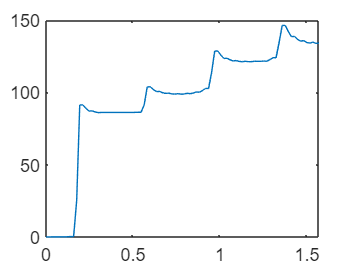


for i = theta_o %Creating different stopping angles from 0 to 90 degrees 
    bounds_of_integration = linspace(0,i,length(integrand)); %use a for loop to continually change the bounds of integration
    finalIntegrand = cumtrapz(bounds_of_integration, integrand);
    apperture_efficiency = (cot(i/2).^2).*(finalIntegrand.^2);
end

plot(linspace(0,pi/2,length(apperture_efficiency)),abs(apperture_efficiency));


[max_efficiency, index_of_max_efficiency] = max(apperture_efficiency)

max_efficiency = -7.5210e+01 + 1.2546e+02i

index_of_max_efficiency = 79

angle_of_max_effieciency = theta_o(index_of_max_efficiency)

angle_of_max_effieciency = 1.3767

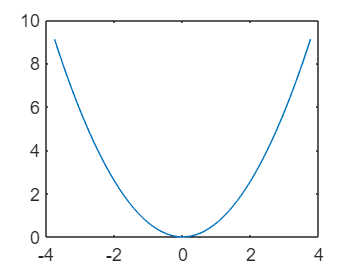

%%Solving for f and zo
d = 7.5; %%length of our reflector in feet

theta_o_1 = theta_o(index_of_max_efficiency);

f = (d / 4) * cot(theta_o_1 / 2);
zo = f - d^2 / (16 * f);

%%making matrixes
V = [1  -d/2 (-d/2)^2;
    1   0   0;
    1   d/2 (d/2)^2];

Y = [f - zo;
    0;
    f - zo];

C = Y \ V; %%note: \ is the operand for matrix division not /

x = -d / 2 : d / 100 : d / 2;
curve = C(1) * x.^2 + C(2) * x;
plot(x, curve);